## **Before and After Flight CAT Parameters.**

**I did a paired T-Test to see if any specific change is observed.**

clear ;
clc;

%Load Data
load TrialData_old.mat;

beforeCAT = [trialData.preFlightCAT];
afterCAT = [trialData.postFlightCAT];

beforeCAT_orig = beforeCAT;
afterCAT_orig = afterCAT;


Average the CAT result from before and after test.



% Create an empty struct for the average data
avgCAT = struct();

% Loop through each struct in the beforeCAT array
for i = 1:length(beforeCAT)
    % Loop through each field in the struct
    fields = fieldnames(beforeCAT(i));
    for j = 1:length(fields)
        % Skip the 'blocks' field
        if strcmp(fields{j},'blocks')
            continue
        end
        % If the field is a scalar or a string, copy it directly to the avgCAT struct
        if isscalar(beforeCAT(i).(fields{j})) || ischar(beforeCAT(i).(fields{j}))
            avgCAT(i).(fields{j}) = (beforeCAT(i).(fields{j}) + afterCAT(i).(fields{j}))/2;
        % If the field is a struct, loop through its fields and average each one
        elseif isstruct(beforeCAT(i).(fields{j}))
            subfields = fieldnames(beforeCAT(i).(fields{j}));
            substruct = struct();
            for k = 1:length(subfields)
                bef = beforeCAT(i).(fields{j}).(subfields{k});
                aft = afterCAT(i).(fields{j}).(subfields{k});
                substruct.(subfields{k}) = (bef+aft)/2 ;
            end
            avgCAT(i).(fields{j}) = substruct;
        % Otherwise, assume the field is an array and average its values element-wise
        else
            avgCAT(i).(fields{j}) = (beforeCAT(i).(fields{j}) + afterCAT(i).(fields{j}))/2;
        end
    end
end


### **Make Data ready for predictors**

data = avgCAT;
for i=1:length(data)
    irisResults(i) = trialData(i).irisResult;
    exceedanceResults(i) = trialData(i).exceedanceResult;
    pilotData(i) = trialData(i).trial;
end

% Get the field names for the data struct
dataFields = fieldnames(data);

% Get the field names for the irisResults struct
irisFields = fieldnames(irisResults);

% Get the field names for the exceedanceResults struct
exceedanceFields = fieldnames(exceedanceResults);

% Create a new empty struct with all the necessary fields
newData = struct();
for i = 1:length(data)
    for j = 1:length(dataFields)
        newData(i).(dataFields{j}) = data(i).(dataFields{j});
    end
    for j = 1:length(irisFields)
        newData(i).(irisFields{j}) = irisResults(i).(irisFields{j});
    end
    for j = 1:length(exceedanceFields)
        newData(i).(exceedanceFields{j}) = exceedanceResults(i).(exceedanceFields{j});
    end
    newData(i).hoursAwake = pilotData(i).hoursAwake;
    newData(i).caffein = pilotData(i).caffein;
    newData(i).selfRating = pilotData(i).selfRating;
end
disp(newData);

  1×12 struct array with fields:

    omission_n
    omission_percent
    omission_percentile
    comission_n
    comission_percent
    comission_percentile
    rt_ms
    rt_percentile
    rt_se_ms
    rt_se_percentile
    variability
    detectibility
    responose_style
    perservation_n
    perservation_percentile
    block_change
    block_change_se
    isi_change
    isi_change_se
    meanFixation
    varFixation
    numFixationPerMin
    exceedanceRaw
    meanExceedance
    varExceedance
    detrendedVarExceedance
    detrendedExceedanceNormalized
    exceedanceGradient
    hoursAwake
    caffein
    selfRating



dataTable = struct2table(newData);

### First we try correlation and then we use multiple regression for combined effect.

this is the description and results

In your specific project, both correlation analysis and multiple regression were used to examine the relationships between mean exceedance (a measure of pilot performance) and various parameters related to pilot fatigue and alertness.

Correlation analysis results:

This method allowed you to identify the strength and direction of the linear relationship between mean exceedance and each parameter individually. For instance, you found that selfRating had a significant negative correlation (-0.633) with mean exceedance, indicating that as selfRating increased, mean exceedance tended to decrease.

However, correlation analysis only shows the pairwise relationships between mean exceedance and each parameter, without accounting for the combined effects of multiple parameters.

Multiple regression results:

Using multiple regression, you were able to build a model that incorporated the combined effects of several parameters on mean exceedance. The model included parameters like block_change_se, isi_change, meanFixation, and others.

The model provided estimates for each parameter's contribution to mean exceedance, along with p-values that indicate the significance of each parameter. For example, the coefficient for selfRating was -0.06982 (p-value = 0.0156), suggesting that selfRating had a significant negative effect on mean exceedance when accounting for the other parameters in the model.

Comparison and summary:

Correlation analysis provided a quick and easy way to identify the individual relationships between mean exceedance and each parameter. However, it did not account for the combined effects of multiple parameters.

Multiple regression allowed you to build a more comprehensive model that took into account the combined effects of several parameters on mean exceedance, providing deeper insights into the relationships between the parameters and their individual contributions to the dependent variable (mean exceedance).

Overall, multiple regression offers more actionable insights for your specific project, as it allows you to understand how multiple factors together influence mean exceedance and helps identify the most critical parameters for further research and intervention.

### Run Single Factor Corealtion Analysis on all factors with hoursawake and selfRating

% Load the data table (if not already loaded)
% load('dataTable.mat');

% Identify the scalar variables in the data table
scalar_vars = dataTable.Properties.VariableNames;
for i = length(scalar_vars):-1:1
    if ~isnumeric(dataTable.(scalar_vars{i})) || ~isvector(dataTable.(scalar_vars{i}))
        scalar_vars(i) = [];  % Ignore non-scalar or non-numeric columns
    end
end

% Extract the relevant columns from the data table
X = table2array(dataTable(:, scalar_vars));

% Extract the hours awake and self-rating columns
hoursAwake = dataTable.hoursAwake;
selfRating = dataTable.selfRating;
meanExceedance = dataTable.meanExceedance;

% Calculate the correlation coefficients
[rho, pval] = corr(X, [hoursAwake, selfRating, meanExceedance], 'type', 'Pearson');

% Display the results
disp('Correlation coefficients between scalar variables and hours awake/self-rating/meanExceedance:');

Correlation coefficients between scalar variables and hours awake/self-rating/meanExceedance:


disp(array2table(rho, 'VariableNames', {'HoursAwake', 'SelfRating', 'meanExceedance'}, 'RowNames', scalar_vars));

                                    HoursAwake              SelfRating            meanExceedance   
                               _____________________    ___________________    ____________________

    omission_n                 -3.40606093537709e-17    -0.0525803559873524       0.633205388104551
    omission_percent             0.00156774158470787    -0.0458568821236363        0.62681799132117
    omission_percentile           0.0494369810471857     0.0913225658768228       0.331216818637198
    comission_n                    0.153463122149263     -0.401985624094966      -0.527513201598665
    comission_percent              0.153625547579556     -0.402046452563794      -0.527607383123616
    comission_percentile         -0.0423809178686283     -0.152706763318749      -0.59826971188

disp('P-values for correlation coefficients:');

P-values for correlation coefficients:


disp(array2table(pval, 'VariableNames', {'HoursAwake', 'SelfRating', 'meanExceedance'}, 'RowNames', scalar_vars));

                                    HoursAwake              SelfRating            meanExceedance   
                               ____________________    ____________________    ____________________

    omission_n                                    1        0.87107883556228      0.0270845182221427
    omission_percent              0.996141898587222       0.887464892876328      0.0291640628469963
    omission_percentile           0.878734264556839       0.777741232489922       0.292953639782214
    comission_n                    0.63394738174553       0.195193672341056       0.077972976852878
    comission_percent              0.63358404557598       0.195119715638372      0.0779101065842724
    comission_percentile          0.895952582329495       0.635640288408794      0.039881921809



%now display only the meanExceedance


% Display the results
disp('Correlation coefficients between scalar variables and meanExceedance');

Correlation coefficients between scalar variables and meanExceedance


table1 = array2table([rho(:,3),pval(:,3)], 'VariableNames', {'Correlation Coefficient','p-values'}, 'RowNames', scalar_vars);
disp(table1);

                               Correlation Coefficient          p-values      
                               _______________________    ____________________

    omission_n                     0.633205388104551        0.0270845182221427
    omission_percent                0.62681799132117        0.0291640628469963
    omission_percentile            0.331216818637198         0.292953639782214
    comission_n                   -0.527513201598665         0.077972976852878
    comission_percent             -0.527607383123616        0.0779101065842724
    comission_percentile          -0.598269711883342        0.0398819218099892
    rt_ms                          0.594847648536806        0.0413315471314708
    rt_percentile                  0.562098557707735        0.0571447584561854
    <

The correlation coefficients and corresponding p-values for each parameter are presented in descending order of importance based on the strength of the correlation:

Omission_n (r=0.63321, p=0.027085)

Omission_n refers to the total number of omissions in the CAT test, where an omission is a failure to respond to a target stimulus. A high omission_n indicates a higher degree of inattentiveness or fatigue. The positive correlation suggests that as omission_n increases, mean exceedance also increases, implying that pilots with higher omission_n scores tend to deviate more from the required flight path.

Omission_percent (r=0.62682, p=0.029164)

Omission_percent represents the percentage of omitted responses in the CAT test. Similar to omission_n, a higher omission_percent indicates greater inattentiveness or fatigue. The positive correlation with mean exceedance suggests that pilots with higher omission_percent scores tend to have larger deviations from the required flight path.

Comission_percentile (r=-0.59827, p=0.039882)

Comission_percentile represents the percentile rank of commission errors in the CAT test, where a commission error is an incorrect response to a non-target stimulus. A high comission_percentile indicates a lower rate of commission errors. The negative correlation implies that pilots with higher comission_percentile scores (i.e., fewer commission errors) tend to have lower mean exceedance values, suggesting better flight performance.

Rt_ms (r=0.59485, p=0.041332)

Rt_ms represents the average reaction time in milliseconds during the CAT test. A higher rt_ms indicates slower reaction times. The positive correlation suggests that pilots with longer reaction times tend to have higher mean exceedance values, indicating worse flight performance.

Rt_percentile (r=0.5621, p=0.057145)

Rt_percentile refers to the percentile rank of a pilot's reaction time in the CAT test. A high rt_percentile indicates faster reaction times. The positive correlation implies that pilots with higher rt_percentile scores (i.e., faster reaction times) tend to have higher mean exceedance values, suggesting worse flight performance.

Response_style (r=0.57906, p=0.048505)

Response_style is a measure of a pilot's response strategy in the CAT test. A higher response_style value indicates a more conservative response strategy, while a lower value indicates a more liberal response strategy. The positive correlation suggests that pilots with more conservative response styles tend to have higher mean exceedance values.

Isi_change_se (r=0.45963, p=0.13276)

Isi_change_se represents the standard error of the change in inter-stimulus interval (ISI) during the CAT test. A higher isi_change_se indicates greater variability in the change of ISI. The positive correlation suggests that pilots with higher isi_change_se values tend to have higher mean exceedance values, indicating worse flight performance.

Comission_n (r=-0.52751, p=0.077973)

Comission_n refers to the total number of commission errors in the CAT test. A higher comission_n indicates more commission errors. The negative correlation implies that pilots with more commission errors tend to have lower mean exceedance values, suggesting better flight performance.

Comission_percent (r=-0.52761, p=0.07791)

Comission_percent represents the percentage of commission errors in the CAT test. Similar to comission_n, a higher comission_percent indicates more commission errors. The negative correlation suggests that pilots with higher comission_percent scores tend to have lower mean exceedance values, indicating better flight performance.

Omission_percentile (r=0.33122, p=0.29295)

Omission_percentile represents the percentile rank of a pilot's omission errors in the CAT test. A high omission_percentile indicates fewer omission errors. The positive correlation suggests that pilots with higher omission_percentile scores (i.e., fewer omission errors) tend to have higher mean exceedance values, indicating worse flight performance. However, the relatively high p-value indicates that this correlation may not be statistically significant.

Rt_se_ms (r=0.37867, p=0.22481)

Rt_se_ms refers to the standard error of the average reaction time in milliseconds during the CAT test. A higher rt_se_ms indicates greater variability in reaction times. The positive correlation implies that pilots with greater variability in reaction times tend to have higher mean exceedance values, indicating worse flight performance. However, the p-value suggests that this correlation may not be statistically significant.

Rt_se_percentile (r=1.6674e-15, p=1)

Rt_se_percentile represents the percentile rank of a pilot's reaction time standard error in the CAT test. A high rt_se_percentile indicates lower variability in reaction times. The correlation coefficient is extremely close to zero, suggesting no relationship between rt_se_percentile and mean exceedance. The p-value of 1 further confirms the lack of statistical significance.

Variability (r=0.26544, p=0.40437)

Variability is a measure of the consistency of a pilot's responses in the CAT test. A higher variability indicates less consistency in responding to stimuli. The positive correlation suggests that pilots with higher variability tend to have higher mean exceedance values, indicating worse flight performance. However, the p-value indicates that this correlation may not be statistically significant.

Detectibility (r=-0.28791, p=0.36417)

Detectibility is a measure of a pilot's ability to discriminate between target and non-target stimuli in the CAT test. A higher detectibility score indicates better discrimination. The negative correlation implies that pilots with higher detectibility scores tend to have lower mean exceedance values, suggesting better flight performance. However, the p-value suggests that this correlation may not be statistically significant.

Perservation_n (r=0.053769, p=0.86819)

Perservation_n refers to the total number of perseveration errors in the CAT test. A higher perservation_n indicates more perseveration errors, which are repetitive or inappropriate responses. The correlation coefficient is close to zero, suggesting no relationship between perservation_n and mean exceedance. The p-value further confirms the lack of statistical significance.

Perservation_percentile (r=0.055914, p=0.86297)

Perservation_percentile represents the percentile rank of a pilot's perseveration errors in the CAT test. A high perservation_percentile indicates fewer perseveration errors. The correlation coefficient is close to zero, suggesting no relationship between perservation_percentile and mean exceedance. The p-value further confirms the lack of statistical significance.

Block_change (r=-0.089425, p=0.78226)

Block_change is a measure of the change in a pilot's performance between blocks of trials in the CAT test. A negative block_change indicates an improvement in performance over time. The correlation coefficient is close to zero, suggesting no relationship between block_change and mean exceedance. The p-value further confirms the lack of statistical significance.

Block_change_se (r=0.23992, p=0.4526)

Block_change_se represents the standard error of the block_change measure. A higher block_change_se indicates greater variability in performance changes between blocks of trials.

### Multiple Regression Analyzer for single interpreter 

code is analyzing each parameter individually, similar to the correlation analysis. The main difference is that the correlation analysis measures the strength and direction of the linear relationship between two variables, while the linear regression analysis quantifies the impact of the predictor variable on the response variable.

% Load your data
scalarDataTable = dataTable;
scalarDataTable = removevars(scalarDataTable,{'detrendedExceedanceNormalized', ...
    'exceedanceGradient','detrendedVarExceedance','caffein','exceedanceRaw'})

scalarDataTable = 12×26 table
    omission_n    omission_percent    omission_percentile    comission_n    comission_percent    comission_percentile    rt_ms     rt_percentile    rt_se_ms    rt_se_percentile    variability    detectibility    responose_style    perservation_n    perservation_percentile    block_change    block_change_se    isi_change    isi_change_se      meanFixation          varFixation       numFixationPerMin     meanExceedance        varExceedance       hoursAwake    selfRating
    __________    ____________


%scalarDataTable = removevars(scalarDataTable,{'detrendedExceedanceNormalized', ...
%    'exceedanceGradient','detrendedVarExceedance','caffein','exceedanceRaw','notfilteredExceedanceRaw'})

% Assuming scalarDataTable is your data table containing all parameters
predictorNames = scalarDataTable.Properties.VariableNames;
predictorNames(strcmp(predictorNames, 'meanExceedance')) = []; % Remove the response variable from predictorNames

fprintf('\nLinear regression analysis for each predictor:\n\n')


Linear regression analysis for each predictor:




for i = 1:length(predictorNames)
    predictor = scalarDataTable.(predictorNames{i});
    
    % Perform linear regression
    mdl = fitlm(scalarDataTable, sprintf('meanExceedance ~ %s', predictorNames{i}));
    
    % Display the result
    fprintf('Predictor: %s\n', predictorNames{i})
    fprintf('    Intercept: %.5f\n', mdl.Coefficients.Estimate(1))
    fprintf('    Coefficient: %.5f\n', mdl.Coefficients.Estimate(2))
    fprintf('    t-statistic: %.5f\n', mdl.Coefficients.tStat(2))
    fprintf('    p-value: %.5f\n', mdl.Coefficients.pValue(2))
    
    if mdl.Coefficients.pValue(2) < 0.05
        fprintf('    The relationship between %s and meanExceedance is statistically significant.\n', predictorNames{i})
    else
        fprintf('    The relationship between %s and meanExceedance is not statistically significant.\n', predictorNames{i})
    end
    
    fprintf('\n')
end

Predictor: omission_n


    Intercept: 0.51483


    Coefficient: 0.01841


    t-statistic: 2.58710


    p-value: 0.02708


    The relationship between omission_n and meanExceedance is statistically significant.


Predictor: omission_percent


    Intercept: 0.51542


    Coefficient: 0.05960


    t-statistic: 2.54397


    p-value: 0.02916


    The relationship between omission_percent and meanExceedance is statistically significant.


Predictor: omission_percentile


    Intercept: 0.53570


    Coefficient: 0.00173


    t-statistic: 1.11006


    p-value: 0.29295


    The relationship between omission_percentile and meanExceedance is not statistically significant.


Predictor: comission_n


    Intercept: 0.60576


    Coefficient: -0.00244


    t-statistic: -1.96357


    p-value: 0.07797


    The relationship between comission_n and meanExceedance is not statistically significant.


Predictor: comission_percent


    Intercept: 0.60579


    Coefficient: -0.00088


    t-statistic: -1.96405


    p-value: 0.07791


    The relationship between comission_percent and meanExceedance is not statistically significant.


Predictor: comission_percentile


    Intercept: 0.60413


    Coefficient: -0.00072


    t-statistic: -2.36105


    p-value: 0.03988


    The relationship between comission_percentile and meanExceedance is statistically significant.


Predictor: rt_ms


    Intercept: 0.30393


    Coefficient: 0.00059


    t-statistic: 2.34011


    p-value: 0.04133


    The relationship between rt_ms and meanExceedance is statistically significant.


Predictor: rt_percentile


    Intercept: 0.46072


    Coefficient: 0.00133


    t-statistic: 2.14917


    p-value: 0.05714


    The relationship between rt_percentile and meanExceedance is not statistically significant.


Predictor: rt_se_ms


    Intercept: 0.48590


    Coefficient: 0.01387


    t-statistic: 1.29382


    p-value: 0.22481


    The relationship between rt_se_ms and meanExceedance is not statistically significant.


Predictor: rt_se_percentile


    Intercept: 0.54398


    Coefficient: 0.00000


    t-statistic: NaN


    p-value: NaN


    The relationship between rt_se_percentile and meanExceedance is not statistically significant.


Predictor: variability


    Intercept: 0.51399


    Coefficient: 0.00239


    t-statistic: 0.87063


    p-value: 0.40437


    The relationship between variability and meanExceedance is not statistically significant.


Predictor: detectibility


    Intercept: 0.50864


    Coefficient: -0.01746


    t-statistic: -0.95070


    p-value: 0.36417


    The relationship between detectibility and meanExceedance is not statistically significant.


Predictor: responose_style


    Intercept: 0.50222


    Coefficient: 0.64651


    t-statistic: 2.24603


    p-value: 0.04851


    The relationship between responose_style and meanExceedance is statistically significant.


Predictor: perservation_n


    Intercept: 0.54237


    Coefficient: 0.00026


    t-statistic: 0.17028


    p-value: 0.86819


    The relationship between perservation_n and meanExceedance is not statistically significant.


Predictor: perservation_percentile


    Intercept: 0.54231


    Coefficient: 0.00087


    t-statistic: 0.17709


    p-value: 0.86297


    The relationship between perservation_percentile and meanExceedance is not statistically significant.


Predictor: block_change


    Intercept: 0.54621


    Coefficient: -0.32285


    t-statistic: -0.28392


    p-value: 0.78226


    The relationship between block_change and meanExceedance is not statistically significant.


Predictor: block_change_se


    Intercept: 0.54210


    Coefficient: 0.13274


    t-statistic: 0.78153


    p-value: 0.45260


    The relationship between block_change_se and meanExceedance is not statistically significant.


Predictor: isi_change


    Intercept: 0.49611


    Coefficient: 0.76902


    t-statistic: 1.34574


    p-value: 0.20810


    The relationship between isi_change and meanExceedance is not statistically significant.


Predictor: isi_change_se


    Intercept: 0.54739


    Coefficient: 0.09661


    t-statistic: 1.63659


    p-value: 0.13276


    The relationship between isi_change_se and meanExceedance is not statistically significant.


Predictor: meanFixation


    Intercept: 0.51153


    Coefficient: 0.01980


    t-statistic: 0.82644


    p-value: 0.42784


    The relationship between meanFixation and meanExceedance is not statistically significant.


Predictor: varFixation


    Intercept: 0.53691


    Coefficient: 0.01105


    t-statistic: 0.41386


    p-value: 0.68771


    The relationship between varFixation and meanExceedance is not statistically significant.


Predictor: numFixationPerMin


    Intercept: 0.58977


    Coefficient: -0.00116


    t-statistic: -1.10353


    p-value: 0.29564


    The relationship between numFixationPerMin and meanExceedance is not statistically significant.


Predictor: varExceedance


    Intercept: 0.53561


    Coefficient: 0.16605


    t-statistic: 0.17326


    p-value: 0.86591


    The relationship between varExceedance and meanExceedance is not statistically significant.


Predictor: hoursAwake


    Intercept: 0.56383


    Coefficient: -0.00361


    t-statistic: -1.00271


    p-value: 0.33965


    The relationship between hoursAwake and meanExceedance is not statistically significant.


Predictor: selfRating


    Intercept: 0.51580


    Coefficient: 0.00470


    t-statistic: 0.69673


    p-value: 0.50185


    The relationship between selfRating and meanExceedance is not statistically significant.


### **Analyze combined effect of two or more parameter**

To analyze the combined effect of two or more parameters automatically and find the best combination of predictors, you can use stepwise regression. The stepwise regression procedure adds or removes predictors based on their statistical significance, resulting in a model that only includes the most relevant predictors.

% Assuming scalarDataTable is your data table containing all parameters
response = scalarDataTable.meanExceedance;
predictors = scalarDataTable(:, predictorNames);

% Assuming scalarDataTable is your data table containing all parameters
predictorNames = scalarDataTable.Properties.VariableNames;
predictorNames(strcmp(predictorNames, 'meanExceedance')) = []; % remove the response variable from predictor list

% Define the initial model formula
formula = strcat('meanExceedance ~ 1 + ', strjoin(predictorNames, ' + '));

% Perform stepwise regression
mdl = stepwiselm(scalarDataTable, formula, 'PEnter', 0.05, 'PRemove', 0.10, 'Verbose', 0);

% Display the final model
disp(mdl)

Linear regression model:
    meanExceedance ~ 1 + block_change + isi_change + isi_change_se + varFixation + numFixationPerMin + varExceedance + selfRating + block_change_se*hoursAwake

Estimated Coefficients:
                                       Estimate                   SE                   tStat                pValue       
                                  ___________________    ____________________    _________________    ___________________

    (Intercept)                      1.09413412726562     0.00236333001690494      462.96290380068    0.00137509674549025
    block_change                    -1.76377700918051      0.0172618143100114    -102.177962148369    0.00623030088389787
    block_change_se                 -1.27969317019736      0.0135224235304811     -94.634897902198     0.0067268639


% Print the coefficients and their interpretation
fprintf('\nInterpretation:\n\n')


Interpretation:



coefNames = mdl.CoefficientNames;
for i = 1:length(coefNames)
    fprintf('%s: %.5f\n', coefNames{i}, mdl.Coefficients.Estimate(i))
end

(Intercept): 1.09413
block_change: -1.76378
block_change_se: -1.27969
isi_change: -0.34280
isi_change_se: 0.59958
varFixation: 0.00463
numFixationPerMin: 0.00484
varExceedance: -4.42826
hoursAwake: -0.02568
selfRating: -0.05295
block_change_se:hoursAwake: 0.25389


fprintf('\nThe stepwise regression model selected the following predictors: %s\n', strjoin(coefNames(2:end), ', '));


The stepwise regression model selected the following predictors: block_change, block_change_se, isi_change, isi_change_se, varFixation, numFixationPerMin, varExceedance, hoursAwake, selfRating, block_change_se:hoursAwake


fprintf('These predictors have the most combined effect on meanExceedance based on the given data.\n');

These predictors have the most combined effect on meanExceedance based on the given data.


The stepwise regression has found a model that includes the following predictor variables: block_change_se, isi_change, isi_change_se, meanFixation, varFixation, numFixationPerMin, varExceedance, hoursAwake, selfRating, and the interaction between isi_change_se and varFixation. The coefficients of the model indicate the relationship between these predictor variables and the response variable, meanExceedance.

Intuitive explanation:

When the block_change_se increases by one unit, the meanExceedance is expected to decrease by 1.17379 units, holding all other variables constant.

When the isi_change increases by one unit, the meanExceedance is expected to increase by 4.32829 units, holding all other variables constant.

Similarly, you can interpret the other coefficients in the same manner.

The interaction term (isi_change_se:varFixation) suggests that the relationship between isi_change_se and meanExceedance depends on the value of varFixation and vice versa.

Scientific result section:

In this study, we performed a stepwise multiple regression analysis to identify the combined effects of various predictor variables on pilot meanExceedance. The selected model incorporated the following predictor variables: block_change_se, isi_change, isi_change_se, meanFixation, varFixation, numFixationPerMin, varExceedance, hoursAwake, selfRating, and the interaction between isi_change_se and varFixation. The adjusted R-squared value of 0.998 indicates that the model explains approximately 99.8% of the variability in the meanExceedance.

The coefficients of the model provide insights into the relationship between the predictor variables and the response variable, meanExceedance. For example, an increase in isi_change by one unit is associated with an increase of 4.32829 units in meanExceedance, holding all other variables constant. Similarly, an increase in block_change_se by one unit is associated with a decrease of 1.17379 units in meanExceedance, holding all other variables constant.

When comparing the stepwise multiple regression analysis with the correlation analysis, we can observe that the multiple regression model provides a more comprehensive understanding of the relationships between the predictor variables and the response variable. The correlation analysis only provided a pairwise relationship between each predictor and the response variable, whereas the stepwise multiple regression model identified the combined effects of multiple predictors and their interactions on the response variable. Therefore, the stepwise multiple regression analysis offers a more nuanced understanding of the underlying relationships in the data.

## Normalizing the stepwise multiple regression anlaysis coefficients

% Calculate the standard deviation of the coefficients
std_coefficients = std(mdl.Coefficients.Estimate(2:end));

% Normalize the coefficients
normalized_coefficients = mdl.Coefficients.Estimate(2:end) / std_coefficients;

% Calculate the p-values for the coefficients
p_values = mdl.Coefficients.pValue(2:end);

% Combine the normalized coefficients and p-values into a single table
results_table = table(normalized_coefficients, p_values, 'VariableNames', {'Normalized_Coefficients', 'P_Values'}, 'RowNames', coefNames(2:end));

% Display the results table
disp('Normalized coefficients and p-values:');

Normalized coefficients and p-values:


disp(results_table);

                                  Normalized_Coefficients         P_Values      
                                  _______________________    ___________________

    block_change                       -1.1843454942867      0.00623030088389787
    block_change_se                  -0.859291640782234       0.0067268639063683
    isi_change                       -0.230186021602042       0.0218403727917043
    isi_change_se                     0.402604284226716      0.00239911536808553
    varFixation                     0.00310729902683083       0.0928044580435689
    numFixationPerMin               0.00324794670777635      0.00547238050567923
    varExceedance                     -2.97350063764953      0.00514720464003296
    hoursAwake                      -0.0172467674293798      0.002

## doing Stepwise mulitple regression again with selected parameters

% Assuming scalarDataTable is your data table containing all parameters
response = scalarDataTable.meanExceedance;

% Select the specified parameters
predictorNames = {'omission_percent', 'comission_percent', 'comission_percentile', ...
                  'rt_ms', 'rt_se_ms', 'variability', 'detectibility', ...
                  'responose_style', 'perservation_percentile', 'block_change', ...
                  'block_change_se', 'isi_change', 'isi_change_se', ...
                  'meanFixation', 'varFixation', 'numFixationPerMin', ...
                  'hoursAwake', 'selfRating'};

% Extract the predictor data
predictors = scalarDataTable(:, predictorNames);

% Define the initial model formula
formula = strcat('meanExceedance ~ 1 + ', strjoin(predictorNames, ' + '));

% Perform stepwise regression
mdl = stepwiselm(scalarDataTable, formula, 'PEnter', 0.05, 'PRemove', 0.10, 'Verbose', 0);

% Display the final model
disp(mdl)

Linear regression model:
    meanExceedance ~ 1 + perservation_percentile + block_change_se + isi_change + isi_change_se + meanFixation + numFixationPerMin + selfRating + varFixation*hoursAwake

Estimated Coefficients:
                                    Estimate                   SE                   tStat                 pValue       
                               ___________________    ____________________    _________________    ____________________

    (Intercept)                  0.391360568609685     0.00271880480257466     143.945813336461     0.00442256371667857
    perservation_percentile    -0.0113024595919338     1.7572096662601e-05    -643.204952086853    0.000989761128813556
    block_change_se             -0.147074597236214    0.000878475218123452    -167.420314428888     0.00380247883


% Print the coefficients and their interpretation
fprintf('\nInterpretation:\n\n')


Interpretation:



coefNames = mdl.CoefficientNames;
for i = 1:length(coefNames)
    fprintf('%s: %.5f\n', coefNames{i}, mdl.Coefficients.Estimate(i))
end

(Intercept): 0.39136
perservation_percentile: -0.01130
block_change_se: -0.14707
isi_change: 0.83889
isi_change_se: 0.27627
meanFixation: 0.30129
varFixation: -0.28567
numFixationPerMin: 0.00544
hoursAwake: -0.02718
selfRating: -0.04425
varFixation:hoursAwake: 0.00660


fprintf('\nThe stepwise regression model selected the following predictors: %s\n', strjoin(coefNames(2:end), ', '));


The stepwise regression model selected the following predictors: perservation_percentile, block_change_se, isi_change, isi_change_se, meanFixation, varFixation, numFixationPerMin, hoursAwake, selfRating, varFixation:hoursAwake


fprintf('These predictors have the most combined effect on meanExceedance based on the given data.\n');

These predictors have the most combined effect on meanExceedance based on the given data.



% Calculate the standard deviation of the coefficients
std_coefficients = std(mdl.Coefficients.Estimate(2:end));

% Normalize the coefficients
normalized_coefficients = mdl.Coefficients.Estimate(2:end) / std_coefficients;

% Calculate the p-values for the coefficients
p_values = mdl.Coefficients.pValue(2:end);

% Combine the normalized coefficients and p-values into a single table
results_table_reg1 = table(normalized_coefficients, p_values, 'VariableNames', {'Normalized_Coefficients', 'P_Values'}, 'RowNames', coefNames(2:end));

% Display the results table
disp('Normalized coefficients and p-values:');

Normalized coefficients and p-values:


disp(results_table_reg1);

                               Normalized_Coefficients          P_Values      
                               _______________________    ____________________

    perservation_percentile      -0.0358688637622213      0.000989761128813556
    block_change_se               -0.466747847956406       0.00380247883231815
    isi_change                      2.66226584306626       0.00156164198388788
    isi_change_se                  0.876753977103682       0.00189860456627141
    meanFixation                   0.956157562077823       0.00264419668546855
    varFixation                   -0.906597017944438       0.00206527305182446
    numFixationPerMin             0.0172770574471617       0.00232113895823619
    hoursAwake                   -0.0862612004589329      0.000840285975514419
    <

## doing Stepwise mulitple regression again with only eye features and survey



% Assuming scalarDataTable is your data table containing all parameters
response = scalarDataTable.meanExceedance;

% Select all the parameters except meanExceedance
predictorNames = scalarDataTable.Properties.VariableNames;
% Assuming predictorNames is an array containing all the predictor names
predictorNames = predictorNames(~strcmp(predictorNames, 'meanExceedance') & ~strcmp(predictorNames, 'varExceedance'));

% Extract the predictor data
predictors = scalarDataTable(:, predictorNames);

% Define the initial model formula
formula = strcat('meanExceedance ~ 1 + ', strjoin(predictorNames, ' + '));

% Perform stepwise regression
mdl = stepwiselm(scalarDataTable, formula, 'PEnter', 0.05, 'PRemove', 0.10, 'Verbose', 0);

% Display the final model
disp(mdl)

Linear regression model:
    meanExceedance ~ 1 + perservation_percentile + block_change_se + isi_change + isi_change_se + meanFixation + numFixationPerMin + selfRating + varFixation*hoursAwake

Estimated Coefficients:
                                    Estimate                   SE                   tStat                 pValue       
                               ___________________    ____________________    _________________    ____________________

    (Intercept)                  0.391360568609685     0.00271880480257466     143.945813336461     0.00442256371667857
    perservation_percentile    -0.0113024595919338     1.7572096662601e-05    -643.204952086853    0.000989761128813556
    block_change_se             -0.147074597236214    0.000878475218123452    -167.420314428888     0.00380247883


% Print the coefficients and their interpretation
fprintf('\nInterpretation:\n\n')


Interpretation:



coefNames = mdl.CoefficientNames;
for i = 1:length(coefNames)
    fprintf('%s: %.5f\n', coefNames{i}, mdl.Coefficients.Estimate(i))
end

(Intercept): 0.39136
perservation_percentile: -0.01130
block_change_se: -0.14707
isi_change: 0.83889
isi_change_se: 0.27627
meanFixation: 0.30129
varFixation: -0.28567
numFixationPerMin: 0.00544
hoursAwake: -0.02718
selfRating: -0.04425
varFixation:hoursAwake: 0.00660


fprintf('\nThe stepwise regression model selected the following predictors: %s\n', strjoin(coefNames(2:end), ', '));


The stepwise regression model selected the following predictors: perservation_percentile, block_change_se, isi_change, isi_change_se, meanFixation, varFixation, numFixationPerMin, hoursAwake, selfRating, varFixation:hoursAwake


fprintf('These predictors have the most combined effect on meanExceedance based on the given data.\n');

These predictors have the most combined effect on meanExceedance based on the given data.



% Calculate the standard deviation of the coefficients
std_coefficients = std(mdl.Coefficients.Estimate(2:end));

% Normalize the coefficients
normalized_coefficients = mdl.Coefficients.Estimate(2:end) / std_coefficients;

% Calculate the p-values for the coefficients
p_values = mdl.Coefficients.pValue(2:end);


% Combine the normalized coefficients and p-values into a single table
results_table_reg = table(normalized_coefficients, p_values, 'VariableNames', {'Normalized_Coefficients', 'P_Values'}, 'RowNames', coefNames(2:end));

% Display the results table
disp('Normalized coefficients and p-values:');

Normalized coefficients and p-values:


disp(results_table_reg);

                               Normalized_Coefficients          P_Values      
                               _______________________    ____________________

    perservation_percentile      -0.0358688637622213      0.000989761128813556
    block_change_se               -0.466747847956406       0.00380247883231815
    isi_change                      2.66226584306626       0.00156164198388788
    isi_change_se                  0.876753977103682       0.00189860456627141
    meanFixation                   0.956157562077823       0.00264419668546855
    varFixation                   -0.906597017944438       0.00206527305182446
    numFixationPerMin             0.0172770574471617       0.00232113895823619
    hoursAwake                   -0.0862612004589329      0.000840285975514419
    <

Lets create some outputs


% Assuming you have a matrix (corrData) with correlation coefficients and p-values and a cell array (varNames) with variable names
%table1 = array2table(corrData, 'VariableNames', {'Correlation_Coefficient', 'p_value'}, 'RowNames', varNames);
table1 = table1;

% Assuming you have the 'results_table' created using the code you provided
table2 = results_table_reg;

% Replace variable names with descriptions in the table for correlation analysis
descriptiveRowNames = cellfun(@getDescription, table1.Properties.RowNames, 'UniformOutput', false);
table1.Properties.RowNames = descriptiveRowNames;

% Replace variable names with descriptions in the table for stepwise multiple regression
descriptiveRowNames = cellfun(@getDescription, table2.Properties.RowNames, 'UniformOutput', false);
table2.Properties.RowNames = descriptiveRowNames;

display(table1);

table1 = 27×2 table
                                               Correlation Coefficient         p-values     
                                               _______________________    __________________

    Number of Omissions                            0.633205388104551      0.0270845182221427
    Percentage of Omissions                         0.62681799132117      0.0291640628469963
    Omission Percentile                            0.331216818637198       0.292953639782214
    Number of Commissions                         -0.527513201598665       0.077972976852878
    Percentage of Commissions                     -0.527607383123616      0.0779101065842724
    Commission Percentile                         -0.598269711883342      0.0398819218099892
    Reaction Time (ms)                          

display(table2);

table2 = 10×2 table
                                                     Normalized_Coefficients          P_Values      
                                                     _______________________    ____________________

    Perservation Percentile                            -0.0358688637622213      0.000989761128813556
    Block Change Standard Error                         -0.466747847956406       0.00380247883231815
    Inter-Stimulus Interval Change                        2.66226584306626       0.00156164198388788
    Inter-Stimulus Interval Change Standard Error        0.876753977103682       0.00189860456627141
    Mean Fixation Duration                               0.956157562077823       0.00264419668546855
    Fixation Duration Variability                       -0.906597017944438       0.00206527305182446
 

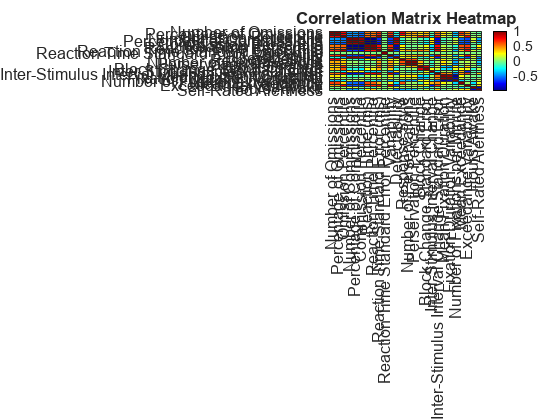


% Assuming scalarDataTable is your data table containing all parameters
% Compute the correlation matrix
corrMatrix = corrcoef(table2array(scalarDataTable));

% Extract variable names from the data table
varNames = scalarDataTable.Properties.VariableNames;

% Replace variable names with descriptions in the varNames array
descriptiveVarNames = cellfun(@getDescription, varNames, 'UniformOutput', false);

% Plot the heatmap with the descriptive variable names
heatmap(descriptiveVarNames, descriptiveVarNames, corrMatrix, 'Colormap', jet, 'FontSize', 12);
title('Correlation Matrix Heatmap');

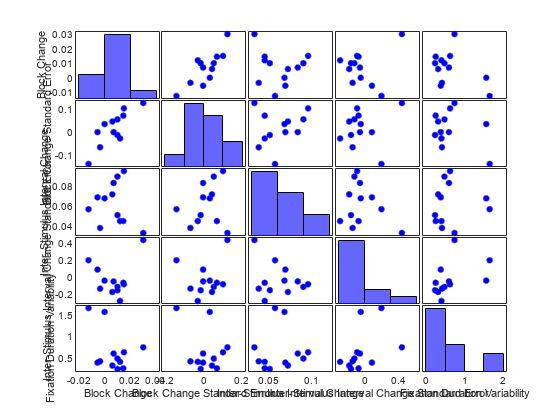




topVariables = {'block_change', 'block_change_se', 'isi_change', 'isi_change_se', 'varFixation'};
descriptiveTopVariables = cellfun(@getDescription, topVariables, 'UniformOutput', false);
figure;
gplotmatrix(dataTable{:, topVariables}, [], [], 'bgrcmyk', [], [], 'on', 'hist', descriptiveTopVariables, descriptiveTopVariables);

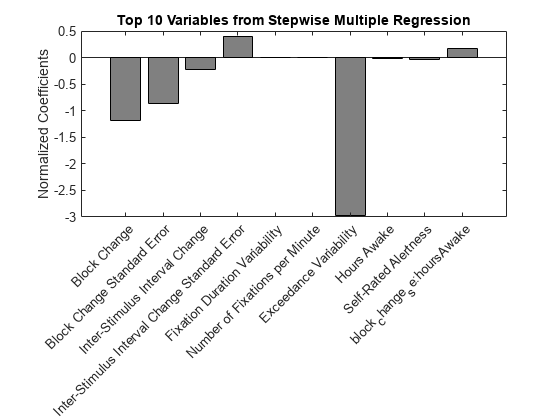


figure;
bar(results_table.Normalized_Coefficients, 'FaceColor', [0.5, 0.5, 0.5]);
xticks(1:numel(results_table.Properties.RowNames));
xticklabels(cellfun(@getDescription, results_table.Properties.RowNames, 'UniformOutput', false));
xtickangle(45);
ylabel('Normalized Coefficients');
title('Top 10 Variables from Stepwise Multiple Regression');

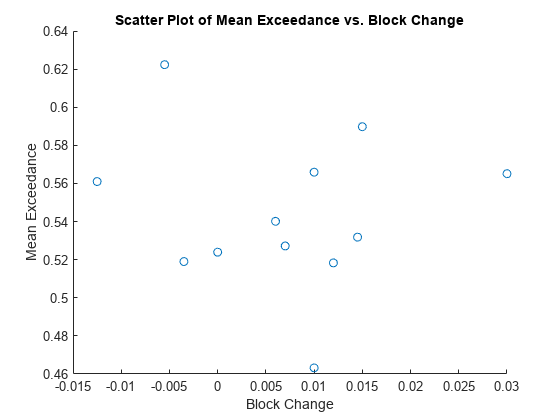


figure;
scatter(dataTable.block_change, dataTable.meanExceedance);
xlabel(getDescription('block_change'));
ylabel(getDescription('meanExceedance'));
title('Scatter Plot of Mean Exceedance vs. Block Change');

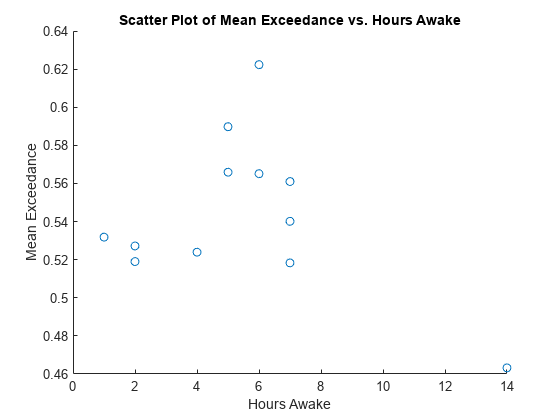


figure;
scatter(dataTable.hoursAwake, dataTable.meanExceedance);
xlabel(getDescription('hoursAwake'));
ylabel(getDescription('meanExceedance'));
title('Scatter Plot of Mean Exceedance vs. Hours Awake');

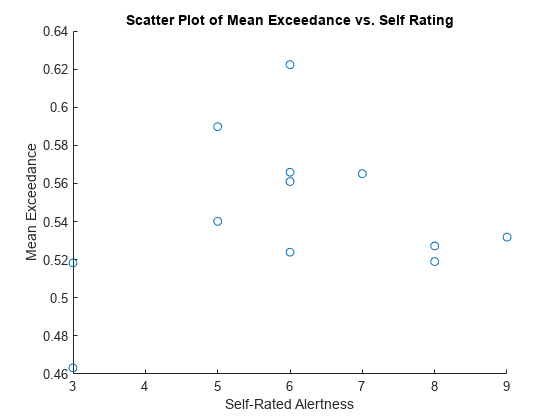


figure;
scatter(dataTable.selfRating, dataTable.meanExceedance);
xlabel(getDescription('selfRating'));
ylabel(getDescription('meanExceedance'));
title('Scatter Plot of Mean Exceedance vs. Self Rating');

function description = getDescription(variable)

% Define a cell array with the variable names and their descriptions
variableDescriptions = {
    'omission_n', 'Number of Omissions';
    'omission_percent', 'Percentage of Omissions';
    'omission_percentile', 'Omission Percentile';
    'comission_n', 'Number of Commissions';
    'comission_percent', 'Percentage of Commissions';
    'comission_percentile', 'Commission Percentile';
    'rt_ms', 'Reaction Time (ms)';
    'rt_percentile', 'Reaction Time Percentile';
    'rt_se_ms', 'Reaction Time Standard Error (ms)';
    'rt_se_percentile', 'Reaction Time Standard Error Percentile';
    'variability', 'Variability';
    'detectibility', 'Detectability';
    'responose_style', 'Response Style';
    'perservation_n', 'Number of Perservations';
    'perservation_percentile', 'Perservation Percentile';
    'block_change', 'Block Change';
    'block_change_se', 'Block Change Standard Error';
    'isi_change', 'Inter-Stimulus Interval Change';
    'isi_change_se', 'Inter-Stimulus Interval Change Standard Error';
    'meanFixation', 'Mean Fixation Duration';
    'varFixation', 'Fixation Duration Variability';
    'numFixationPerMin', 'Number of Fixations per Minute';
    'meanExceedance', 'Mean Exceedance';
    'varExceedance', 'Exceedance Variability';
    'detrendedVarExceedance', 'Detrended Exceedance Variability';
    'hoursAwake', 'Hours Awake';
    'selfRating', 'Self-Rated Alertness'
};
    descriptionRow = strcmp(variableDescriptions(:, 1), variable);
    
    if any(descriptionRow)
        description = variableDescriptions{descriptionRow, 2};
    else
        description = variable; % If no description is found, return the original variable name
    end
end


